lambda = 10;
exact = @(x) sinh(lambda*x)/sinh(lambda) - 1;

These functions must accept and return vectors. 

p = @(x) 0*x;            
q = @(x) -lambda^2*x.^0;
r = @(x) lambda^2*x.^0;

We compare the computed solution to the exact one for increasing $n$. 

n = [32 64 128 256 512]';
error = 0*n;
for k = 1:length(n)
    [x,u] = bvplin(p,q,r,[0 1],-1,0,n(k));
    
    error(k) = norm(exact(x)-u,inf);
end

table(n,error)

ans = 5×2 table
     n            error        
    ___    ____________________

     32     0.00148047060983891
     64    0.000372619268345087
    128    9.34931452077903e-05
    256    2.33830547288205e-05
    512    5.84703544947995e-06


Each time $n$ is doubled, the error is reduced by a factor very close to 4, which is indicative of second order convergence.

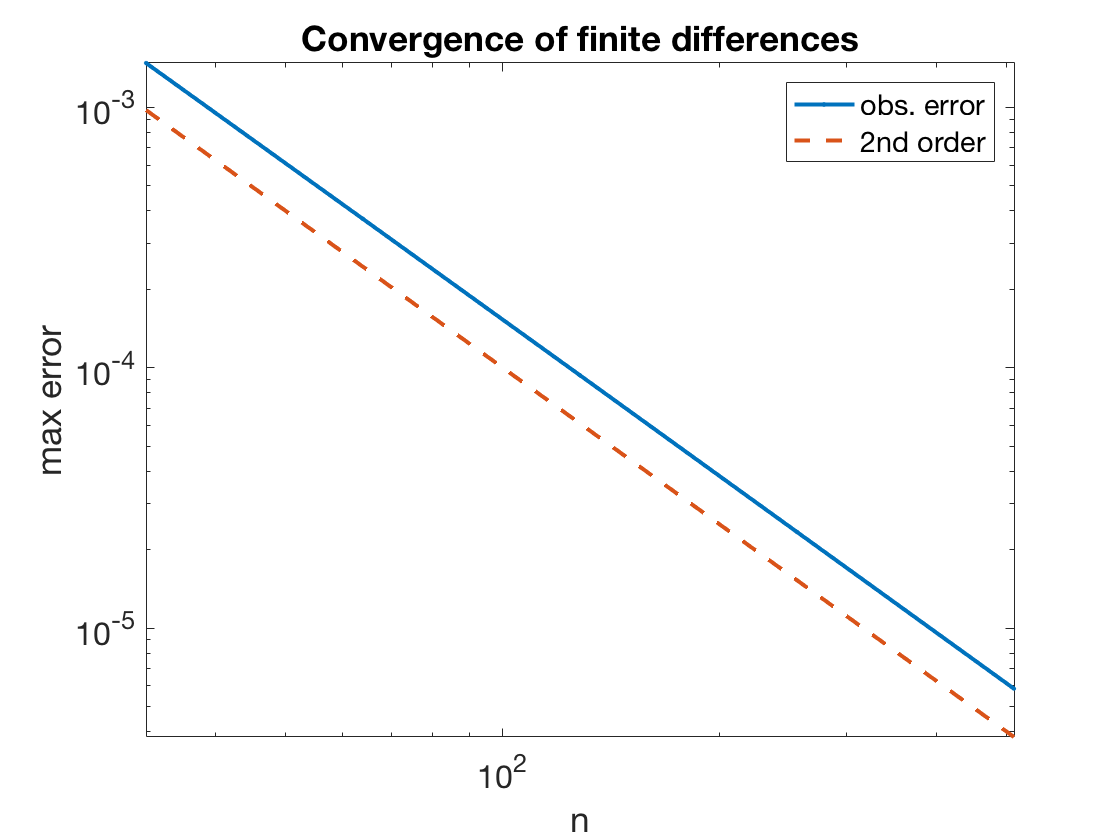

loglog(n,error,'.-')
hold on, loglog(n,n.^(-2),'--')
xlabel('n'), ylabel('max error')   % ignore this line
title('Convergence of finite differences')    % ignore this line
legend('obs. error','2nd order')   % ignore this line
axis tight    % ignore this line